# 蒙特卡洛模拟：引例，投针实验

## 预备知识

rand: 此 MATLAB 函数 返回一个在区间 (0,1) 内均匀分布的随机数。

rand(3) % 返回一个3阶矩阵
rand(5,4) % 返回一个5*4的矩阵
% 若想获取[a, b]范围的随机数:
% a + rand(m, n) * (b - a) 返回m行n列矩阵,范围在: [a, b]
% -1 + rand(3,2) * (5 - (-1)) % 返回3行2列的矩阵,范围在[-1,5]
% 更高级的函数: unifrand
% unifrnd(a, b, m, n) 返回m行n列,范围[a, b]的随机数
unifrnd(-1,5, 5,9) % 返回一个5行9列范围[-1, 5]的随机数

## 代码部分 用蒙特卡洛方法 模拟浦丰投针

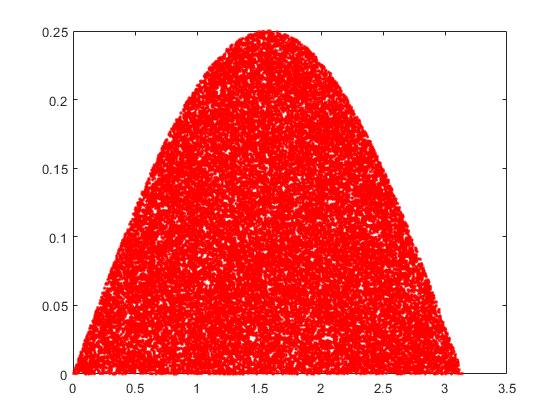

tic % 启动秒表计时器
n = 100000; % 迭代次数
l = 0.5; % 针的长度
d = 1; % 线与线之间的宽度
m = 0; % 针与线相交的次数
% 抽象模型, x是针中心到两边的线最近EW的距离, phi表示针与线的夹角
x = rand(1,n) * d / 2; % 返回1*n矩阵, 返回[0,d/2]随机数(服从均匀分布)
phi = rand(1, n) * pi; % 在[0, pi]中服从均匀分布


figure(1)
% axis(limits) 用于设置坐标轴范围和横纵比。以包含 4 个、6 个或 8 个元素的向量形式指定范围。
% axis(x1,x2, y1,y2):设置x坐标轴区域：x1到x2. y坐标轴区域:y1到y2
axis([0,pi, 0,d/2]) % 设置x:[0,pi],y[0,d/2]
for i = 1 : n % 开始迭代, 一次看每根针是否与平行线相交
    if x(i) <= (l/2) * sin(phi(i)) % 说明此时相交
        m = m + 1; % 相交次数+1
        % 画图:
        plot(phi(i), x(i), 'r.')
        hold on
%         pause(0.01)
        
    end
    
end


% p = 2*l/pi*d = m / n, 所以根据公式:pi = 2 * l / d * p
p = m / n % 针相交于平行的概率

p = 0.3181

simulatePi = (2 * l)/(d * p) % 我们根据公式就可以计算得到的pi值

simulatePi = 3.1436


disp(['蒙特卡洛模拟得到的相交的概率:',num2str(p), ', pi值:' ,num2str(simulatePi)])

蒙特卡洛模拟得到的相交的概率:0.31811, pi值:3.1436


toc % 读取秒表计时器

历时 42.461499 秒。


## 一次实验具有随机性,偶然性,所以我们做一百次实验,然后取一个平均值

tic % 启动秒表计时器
count = 100;
n = 1000; % 迭代次数
l = 0.5; % 针的长度
d = 1; % 线与线之间的宽度
m = 0; % 针与线相交的次数
% 抽象模型, x是针中心到两边的线最近EW的距离, phi表示针与线的夹角
x = rand(1,n) * d / 2; % 返回1*n矩阵, 返回[0,d/2]随机数(服从均匀分布)
phi = rand(1, n) * pi; % 在[0, pi]中服从均匀分布
% 创建结果矩阵：
result_pi = zeros(1,count);
result_p = zeros(1,count);


for k = 1:count
    for i = 1 : n % 开始迭代, 一次看每根针是否与平行线相交
        if x(i) <= (l/2) * sin(phi(i)) % 说明此时相交
            m = m + 1; % 相交次数+1
            % 这里就不画图了，因为画图很消耗资源和时间
    %         plot(phi(i), x(i), 'r.')
    %         hold on
    %         pause(0.01)
            
        end
    end
    result_p(k) = m / n; % 针相交于平行的概率
    result_pi(k) = (2 * l)/(d * p); % 我们根据公式就可以计算得到的pi值

end


disp(['蒙特卡洛模拟得到相交的概率(平均值):',num2str(mean(result_p)), ', pi值(平均值):' ,num2str(mean(result_pi))])
toc % 读取秒表计时器